# Sequence Classification by Sweeping Hyperparameters

This template function defines the training data, network architecture, and training options for a sequence classification experiment. Experiment Manager uses the outputs of this function to call the [`trainNetwork`](matlab:doc('trainNetwork')) function. For more information on sequence classification, see [Sequence Classification Using Deep Learning](matlab:helpview('deeplearning','ClassifySequenceDataUsingLSTMNetworksExample')). For more information on built-in experiments, see [Configure Built-In Training Experiment](matlab:helpview('deeplearning','exp-mgr-create-experiment')).

Modify this function as a template to set up your own experiment.

## Input

- `params` is a structure with fields from the Experiment Manager hyperparameter table.

## Output

- `traindata` is a cell array containing sequences of varying length. 

- `trainlabels` is a categorical vector of labels.

- `layers` is a layer graph that defines the neural network architecture.

- `options` is a `trainingOptions` object.

[traindata, trainlabels, layers, options] = RobotExperiment();

## Train the network

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       38.46% |       40.95% |       1.1806 |       1.2770 |          0.0100 |
|      50 |          50 |       00:00:19 |       86.16% |       85.59% |       0.3295 |       0.4251 |          0.0100 |
|     100 |         100 |       00:00:30 |       90.64% |       87.21% |       0.2117 |       0.3002 |          0.0100 |
|     150 |         150 |       00:00:40 |       95.93% |       92.61% |       0.1060 |       0.2356 |          0.0100 |
|     20

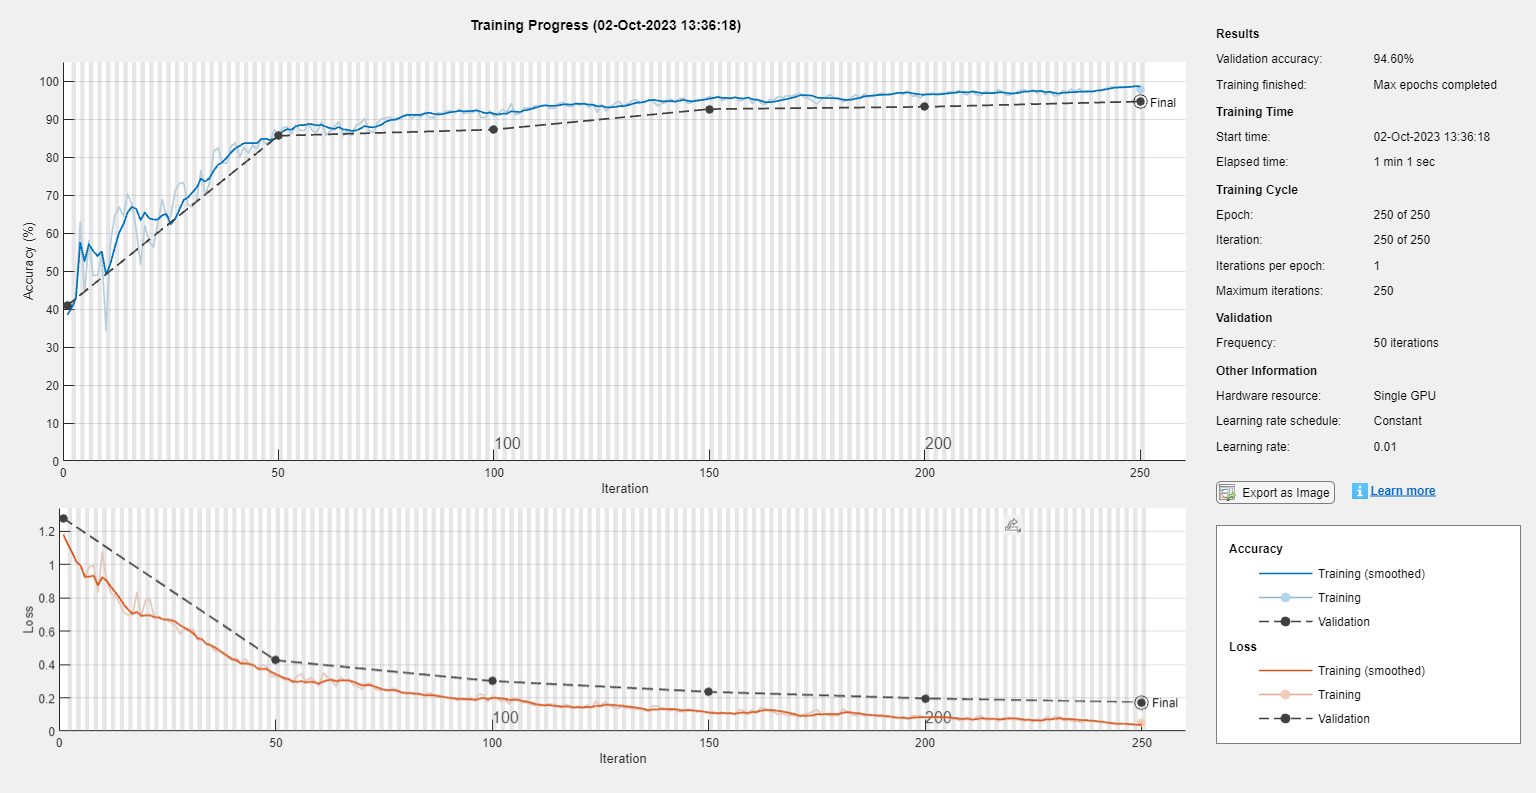

robonet = trainNetwork(traindata, trainlabels, layers, options);

function [traindata, trainlabels, layers, options] = RobotExperiment()

## Load Training Data

Change the variable pathToSignals to the location of the `robotdata` folder on your computer.

    pathToSignals = "../data/robotdata";
    robods = signalDatastore(pathToSignals, "SignalVariableNames", ["front" "left"], "ReadOutputOrientation", "row");
    transds = transform(robods, @prepsig);
    sigdata = readall(transds);
    
    labelds = signalDatastore(pathToSignals, "SignalVariableNames", "direction");
    transds = transform(labelds, @preplabel);
    labels = readall(transds);

Separate training, validation, and testing observations

    traindata = sigdata(1:3);
    trainlabels = labels(1:3);
    valdata = sigdata{4};
    vallabels = labels{4};

## Define Network Architecture

Define the convolutional neural network architecture in the layer graph `layers`. 

    inputSize = 2;
    numHiddenUnits = 100;
    numClasses = 4;
    layers = [  sequenceInputLayer(inputSize)
                bilstmLayer(numHiddenUnits, "OutputMode", "sequence")
                fullyConnectedLayer(numClasses)
                softmaxLayer
                classificationLayer];

Replace the layer graph with your own layer graph to train. For more information, see [List of Deep Learning Layers](matlab:helpview('deeplearning','list_of_layers')).

## Specify Training Options

Call the [`trainingOptions`](matlab:doc('trainingOptions')) function to specify the training options for the experiment. Read the hyperparameters specified in Experiment Manager by accessing the fields of the input `params`. For example, access the initial learning rate `myInitialLearnRate` defined in the hyperparameter table with the argument value `params.myInitialLearnRate`.

    options = trainingOptions(  "adam", ...
                                "ValidationData", {valdata vallabels},...
                                "GradientThreshold", 1, ...
                                "MaxEpochs", 250, ...
                                "SequenceLength", "longest", ...
                                "InitialLearnRate", 1e-2, ...
                                "Verbose", true, ...
                                "Plots", "training-progress");

End of experiment setup function.

end

Format the signals for training

function sigout = prepsig(sig)
    sigmatrix = cell2mat(sig);
    sigtranspose = sigmatrix';
    sigout = {sigtranspose};
end

Format the labels for training

function [labelout] = preplabel(label)
    labelcat = categorical(label);
    labeltranspose = labelcat';
    labelout = {labeltranspose};
end

*Copyright 2020-2022 The MathWorks, Inc.*